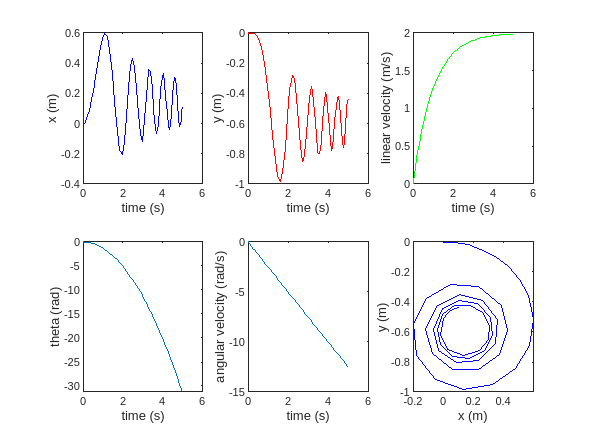

% design vector x: first N/2 elements are left torques, last N/2 elements
% are right torques
x = [ones(8, 1); zeros(8, 1)];

% simulate the single shooting trajectory
% state vector q = [x, y, v, theta, thetadot]
[tout, yout] = sim_trajectory_single_shooting(x);

% Plot all states and trajectory
figure
hold on
subplot(2, 3, 1);
plot(tout, yout(:,1), 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(tout, yout(:,2), 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(tout, yout(:,3), 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(tout, yout(:,4))
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(tout, yout(:,5))
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(yout(:,1), yout(:,2), 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

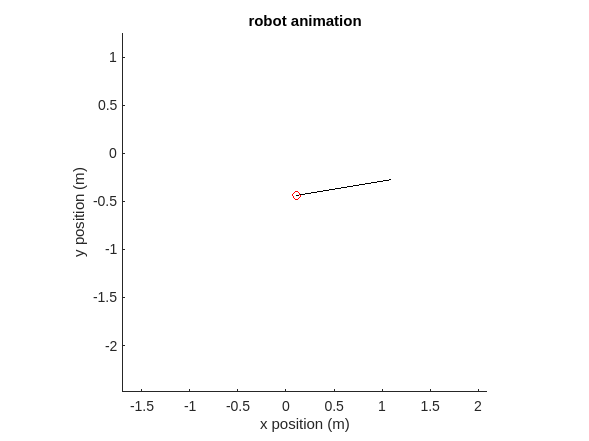


% animate the trajectory
animate_single_shooting(tout, yout)

% use symbolic toolbox to define dynamics function
%{
syms L M d J R b
syms q [5 1]
syms u [2 1]

q_dot = [q(3)*cos(q(4));
         q(3)*sin(q(4));
         d*q(5)^2 + (u(2) + u(1))/(M*R) - b*q(3);
         q(5);
         L/(M*d^2 + J) * (u(2) - u(1))/R - M*d/(M*d^2 + J) * q(3)*q(5)];
matlabFunction(q_dot, "File", "odefun_torque.m", "Vars", {q, u, L, M, d, J,
R, b});
%}
